MRN_st.name='MRN'; 
MRN_st.lat=46.7583;
MRN_st.lon=-122.124;
MRN_st.alt=439;
MRN_st.env='con';
MRN_st.footp='F';


MRN_rd=read_betsy('MRN_head',MRN_st.name);

datevec(MRN_rd.Time(1))

ans =         1993           1           2           0           0           0

datevec(MRN_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(MRN_rd.U_S11,[5 50 95])

ans =    68.1733   92.1000  100.2357

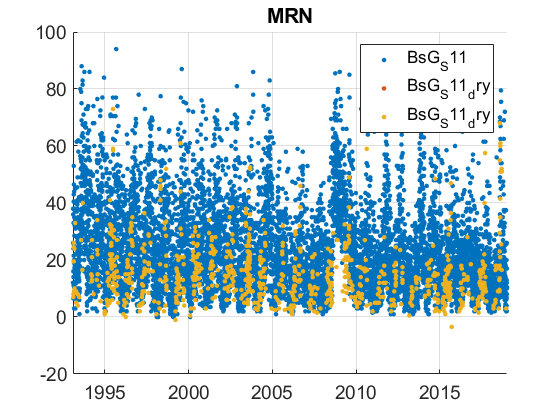

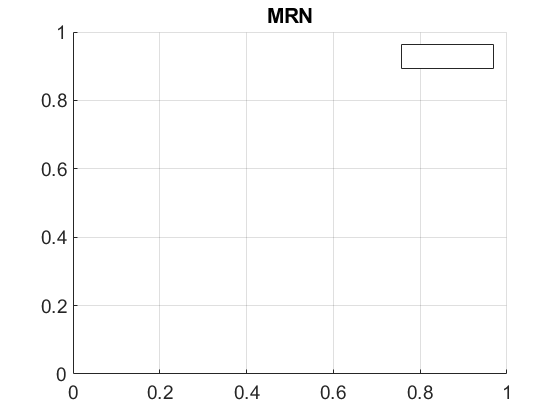

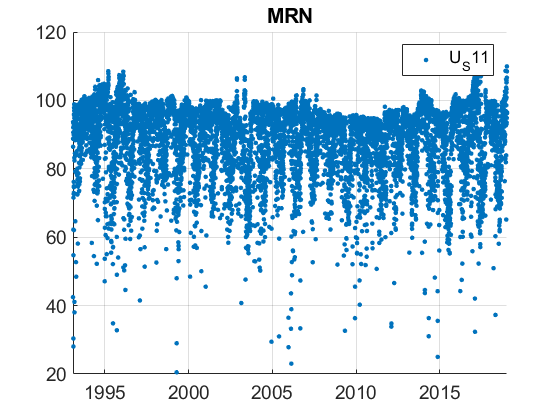

plotFigControl(MRN_rd,MRN_st.name);

% 1 size cut, ok
% sc: ok, max in summer, few negatives



% % lambdaSC=[450;550;700]*ones(1,4);
% % lambdaAE3=[467;530;660]*ones(1,4);
% % lambdaAE7=[370 470 520 590 660 880 950];
% % MRN_cal=compute_exp_SSA(MRN_rd,lambdaSC, lambdaAE);
% % plotFigControl_cal(MRN_cal,MRN_st.name);

%Questions:
%problems:
% data too high from August 2008 to June 2009: can you correct it ?

MRN_tr=MRN_rd;
MRN_tr.y=year(MRN_tr.Time);
%eneleve une valeur de 2019
MRN_tr=MRN_tr(1:end-1,:);
% begin at the beginning of a year: 1993
% end: 2018
P=timerange('1993-01-01','2019-01-01');
MRN_tr=MRN_tr(P,:);
%probably instrument change  from August 2008 to June 2009
period=timerange('2008-08-01','2009-07-01');
MRN_tr.BsG_S11(period)=NaN;
MRN_tr.BsG_S11_dry(period)=NaN;

names=fieldnames(MRN_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    MRN_tr.(N{i})=[];
end
% dry= almost no data!!

MRN_result= all_trend_STN(MRN_tr,MRN_st); 

MRN_result_D=MRN_result;
